# Celebrating Spring: MATLAB Tulip

Joining us again is Eric Ludlam, development manager of MATLAB’s charting team. Discover more about Eric on our [contributors bio page.](https://blogs.mathworks.com/graphics-and-apps/contributors/) Last time Eric was here, [Daffodils were on his mind](https://blogs.mathworks.com/matlab/2023/04/14/celebrating-springtime-the-matlab-daffodil/). Now, he focuses on tulips. 

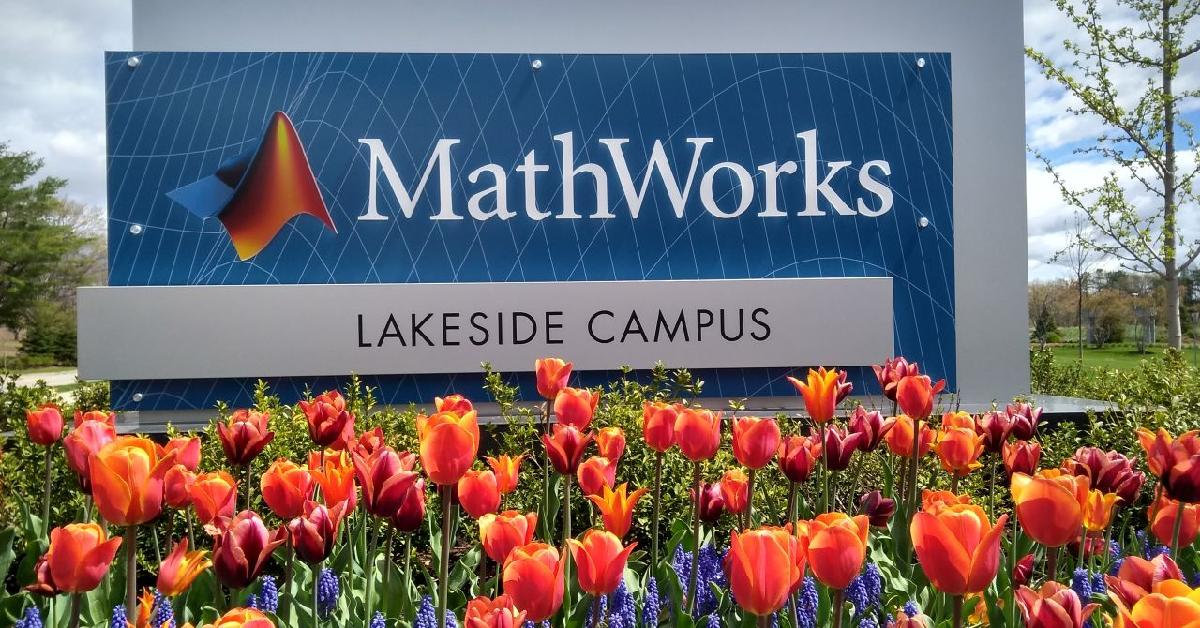

Spring is here in Natick and the tulips are blooming!   While tulips appear only briefly here in Massachusetts, they provide a lot of bright and diverse colors and shapes.  To celebrate this cheerful flower, here's some code to create your own tulip!

This script uses some fun tricks, like extracting a subset of the 'hot' colormap for a red-to-yellow colormap, and specifying several material properties to give it a more sunny day look. There's also the [sinpi and cospi functions that Mike likes so much](https://blogs.mathworks.com/matlab/2022/10/21/sinpi-cospi-implicit-expansion-and-the-2022-matlab-mini-hack/?s_tid=srchtitle_site_search_1_sinpi)! 

Explore the code and create some new breeds of tulips for your MATLAB.

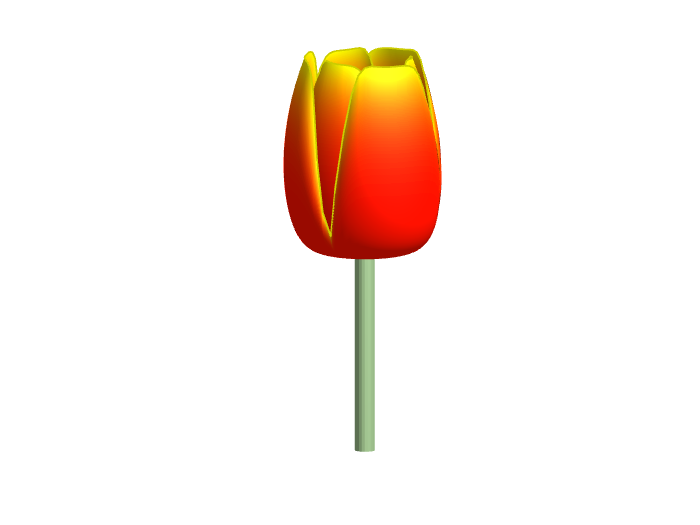

%% MATLAB Tulip
np = 3; % number of petals
n=np*20+1; % Theta resolution
theta=linspace(0, np*(1/np)*2,n);
r=linspace(0,1,80)';

newplot
for k=[0 1/np] % 2 layers of petals
    x=1-(.8*(1-mod(np*(theta+k),2)).^3-.05).^2/2;
    Z1=((x.*r).^6);
    R2=x.*r*(1-k*.38);
    R3=x.*(r.^8)*.4.*Z1;
    X=R2.*cospi(theta)-R3.*cospi(theta);
    Y=R2.*sinpi(theta)-R3.*sinpi(theta);
    C=repmat(r,1,n).^25;
    %% Petals
    surface(X,Y,Z1*2,C,FaceColor="interp",EdgeColor="none",FaceLighting="gouraud");
    line(X(end,:),Y(end,:),Z1(end,:)*2,Color="#cc0",LineWidth=1);
end
%% Stem
[CX,CY,CZ]=cylinder;
surface(CX*.1,CY*.1,(CZ-1)*2,[],FaceColor="#9b8",EdgeColor="none");
%% Decorate!
cmap=hot(200); % Colors of tulip
colormap(cmap(80:150,:)) % Extract subset of hot colormap.
axis off equal
view([0,10]);
material([.6 .9 .3 2 .5])
camlight(40,40)